# Day 6 - Initial Data Visualizations

[lr_accel, lr_gyro] = parsePowerSenseData_1('12inchtest_90bpm.csv');

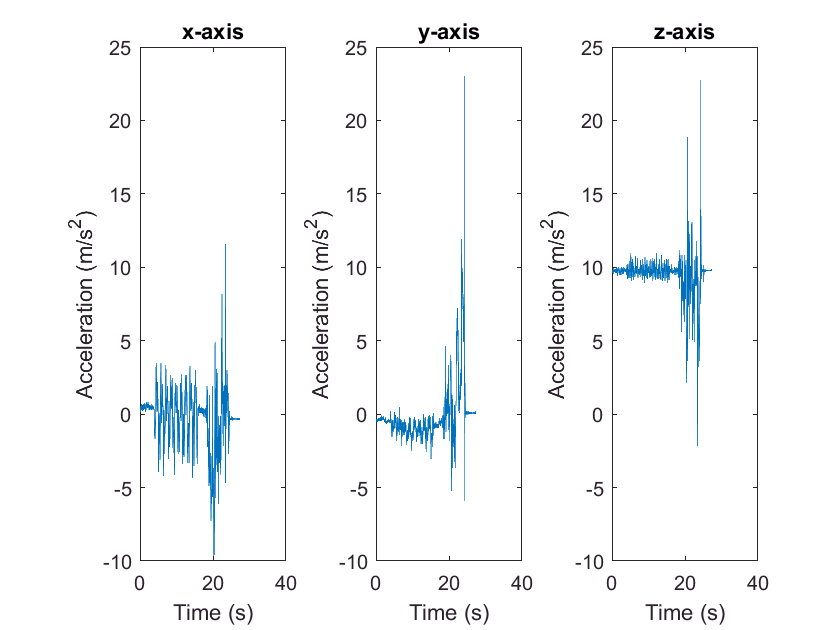

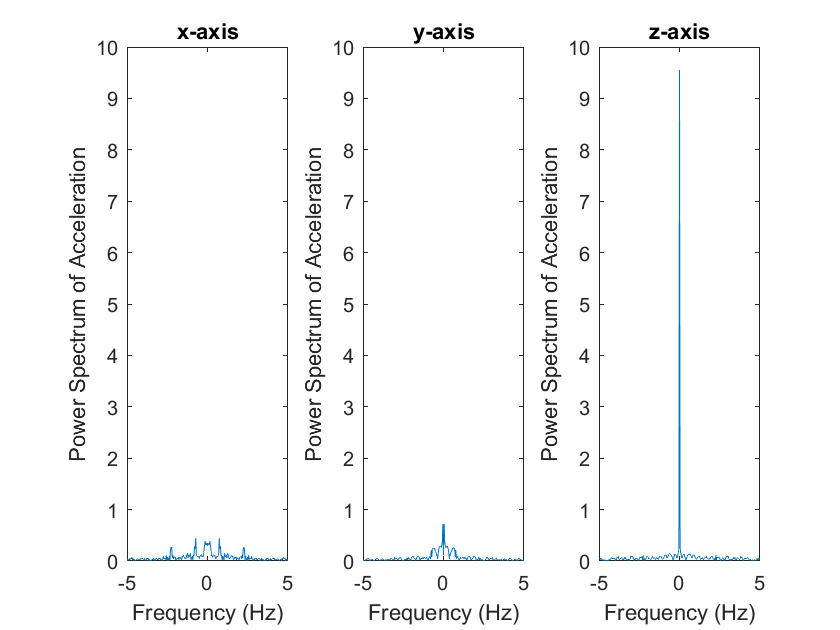

makeAccelerometerPlots(lr_accel,[],true)

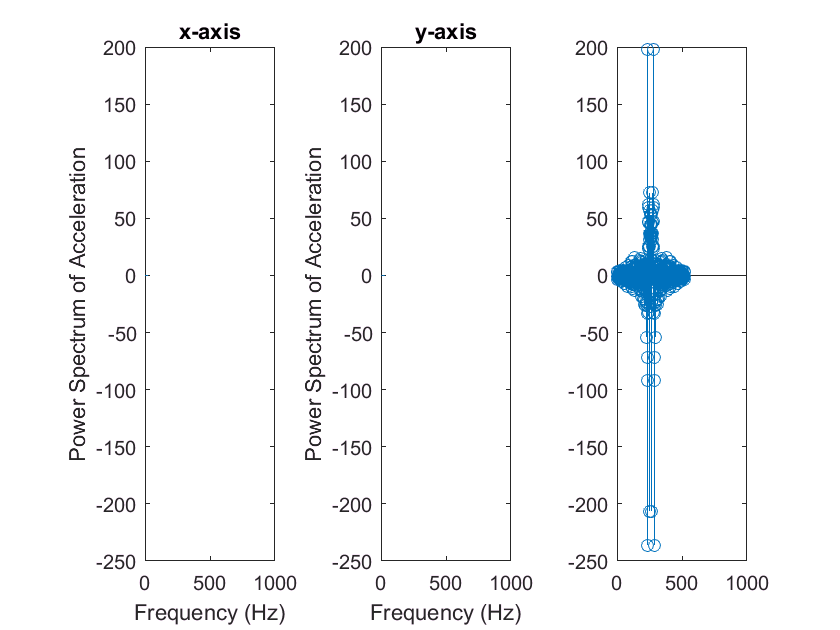

startcut = 280;
endcut = 800;

x_accel = lr_accel(:,2);
x_accel = x_accel(startcut:endcut);
plot(x_accel)
fft_x = real(fft(x_accel));
fft_xshift = fftshift(fft_x);

[~, i] = max(fft_xshift);
stem(fft_xshift)

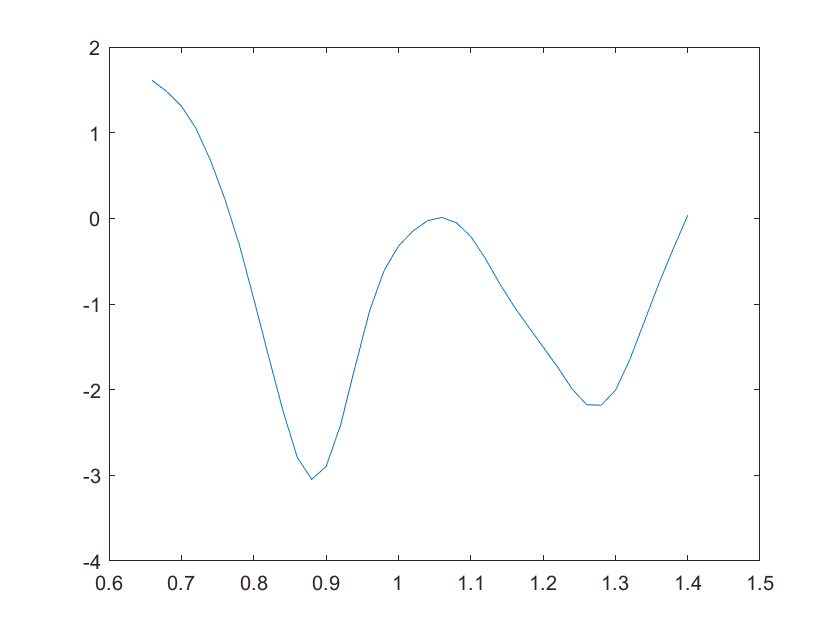

Fs = 1/lr_accel(2,1)-(lr_accel(1,1));

% make_freq_plot(x_accel, Fs)


h = [1/4 1/4 1/4 1/4];          % moving average shape
x_accel = conv(x_accel, h);     % moving average convolution
x_accel = x_accel(1:(end-length(h)+1)); % adjusting for conv
x_accel = conv(x_accel,h);      % move the average again
x_accel = x_accel(1:(end-length(h)+1)); % adjusting for conv
x_times = lr_accel(:,1);        % grab times column
x_times = x_times(startcut:endcut);     % cutoff bad data
x_times = x_times-x_times(1);   % center unex times

period1 = 34:71;
xacc_int = x_accel(period1);
xtime_int = x_times(period1);

velocity = cumtrapz(xtime_int, xacc_int);
position = cumtrapz(xtime_int, velocity);

figure
plot(xtime_int, xacc_int)

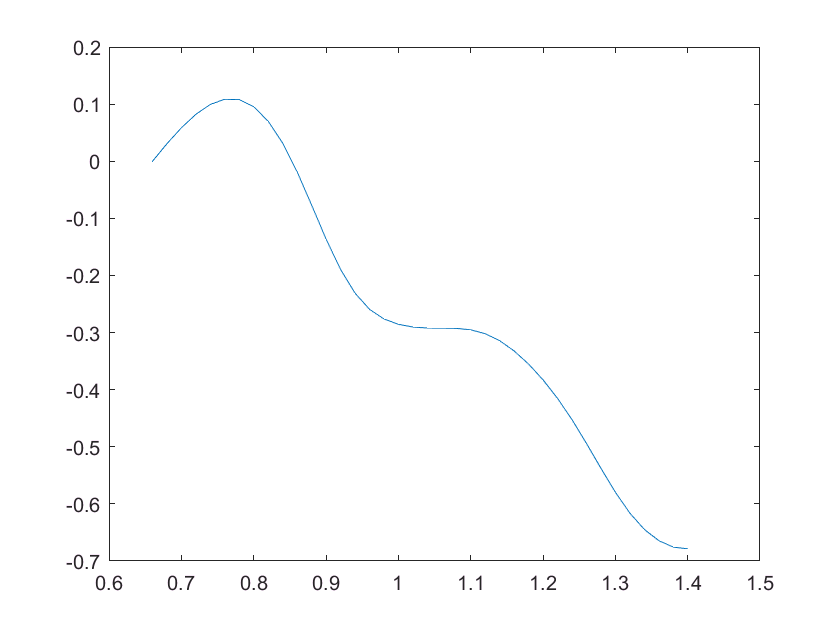

plot(xtime_int, velocity)

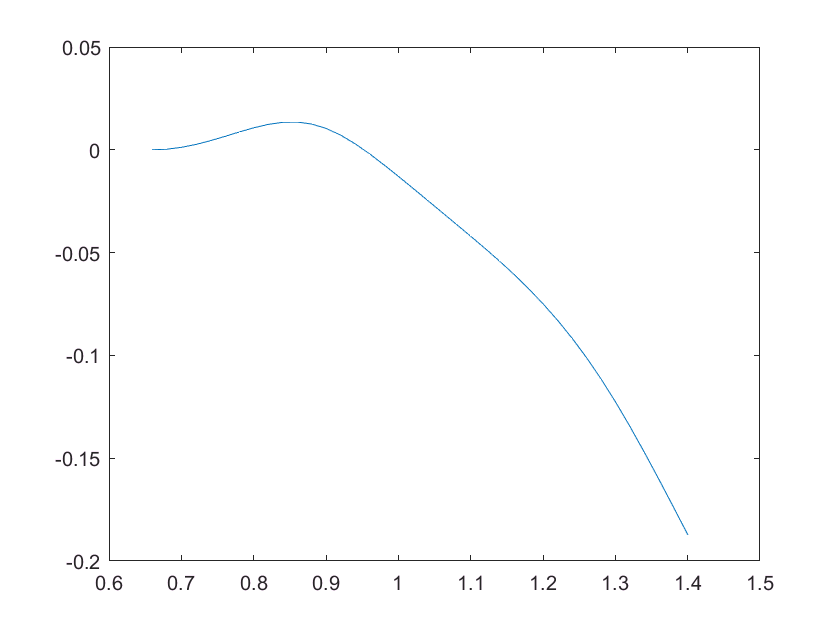

plot(xtime_int, position) 

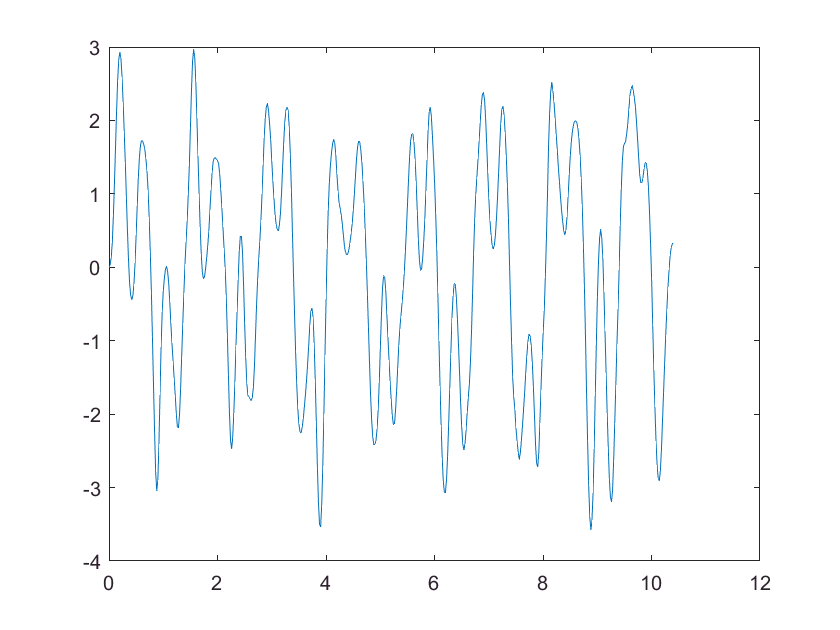

plot(x_times, x_accel)

# Square Conducting Analysis

[square_accel, square_gyro] = parsePowerSenseData_1('square90bpm.csv');

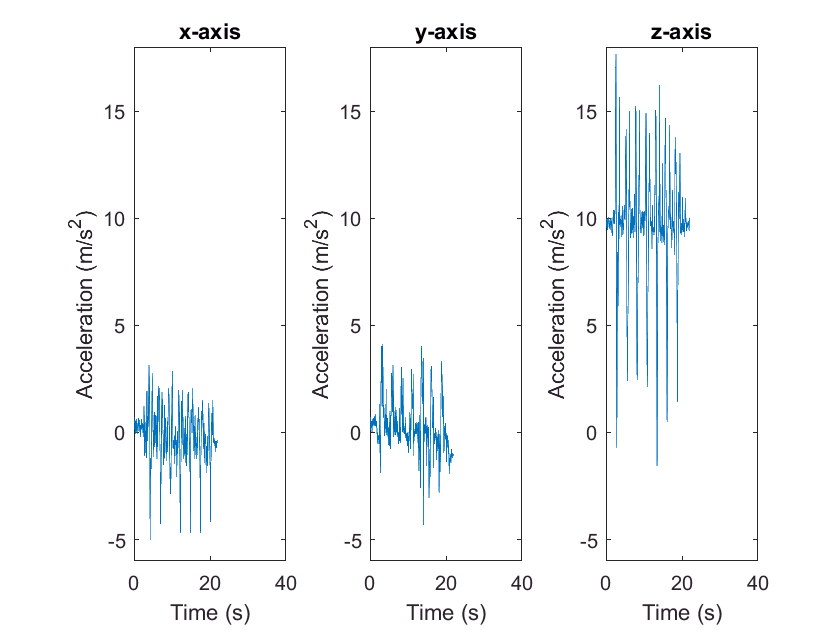

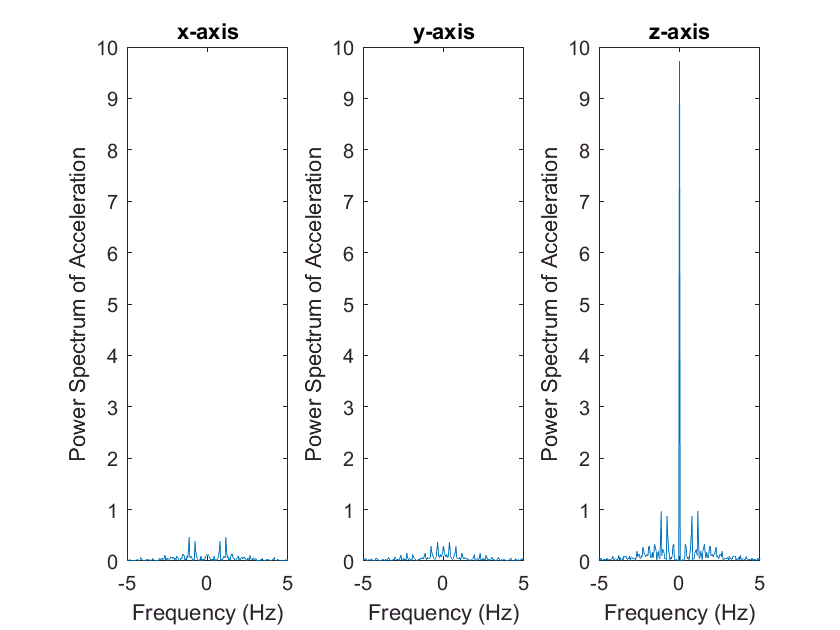

makeAccelerometerPlots(square_accel,[],true)